LATER Fitting Exercise

 Copyright 2023 by Joshua I. Gold, University of Pennsylvania

    The basic idea in fitting a model to data is to find the parameters of the model that provide in some sense the best match of the model to the data. This match is provided by the "objective function." This exercise is intended to demystify this process by getting you to define the initial conditions and objective function for fitting the LATER model to RT data. For a much more thorough, but still very accessible, overview of model fitting (to behavioral data), here is a great place to start: [https://elifesciences.org/articles/49547](https://elifesciences.org/articles/49547)

    For this exercise, recall that the point of the LATER model is that 1/RT is distributed as a Gaussian, where we can define the parameters of the Gaussian (mu and sigma) with respect to the standard parameters of the LATER model (muR and deltaS):

      mu = muR/deltaS

      sigma = 1/deltaS

     So fitting LATER to behavioral data involves finding parameters muR and deltaS that provide the best match to the data, according to the appropriate objective function. Follow along the steps below, some of which will require you to complete the code (and therefore hopefully think about how to relate the high-level concepts discussed above with the nitty-gritty part of getting everything to actually work.

GlobalSearch stopped because it analyzed all the trial points.

All 6 local solver runs converged with a positive local solver exit flag.
GlobalSearch stopped because it analyzed all the trial points.

All 70 local solver runs converged with a positive local solver exit flag.
GlobalSearch stopped because it analyzed all the trial points.

All 5 local solver runs converged with a positive local solver exit flag.
GlobalSearch stopped because it analyzed all the trial points.

All 34 local solver runs converged with a positive local solver exit flag.


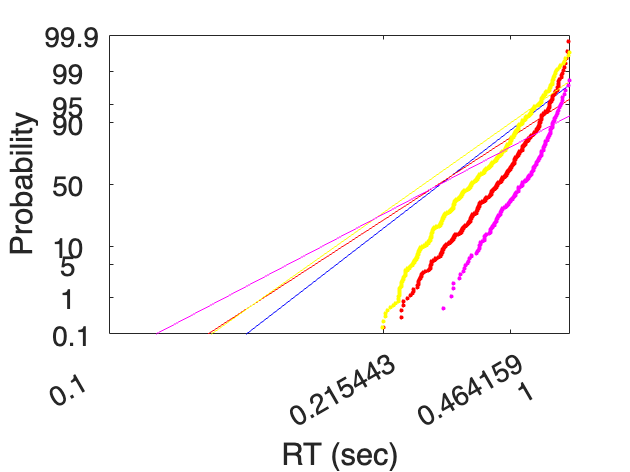

%%  1. Get the data
%   
%   Use this code to get a data set (array of RTs from a single condition) 
%   to fit, already preprocessed to include correct trials only and remove
%   outliers (including express saccades). See later_getData for details
[data,labels] = later_getData([], [], 0.2);
RTs = data{1};
%clear data

%%  2. Define the objective function
%
% The objective function typically defines the error that you want to 
% minimize between your data and the model predictions. A common objective 
% function is the negative of the sum of the log-likelihoods of the data, 
% given the model parameters. To unpack that for the LATER model:
%
%   1. For each data point (RT from a single trial, in this case) and given
%       set of model parameters, compute the probability of the data, given
%       the model (i.e., the likelihood)
%   2. Take the logarithm
%   3. Sum all these log-likelihoods from all the data points
%   4. Take the negative, because we want to find the minimum (thus
%        corresponding to the maximum likelihood)
 
% EXERCISE:
% laterErrFcn = @(fits) <**YOUR OBJECTIVE FUNCTION HERE AS A FUNCTION OF FITS**>;
for ii= 1:length(labels)
    reciprocalRTs=1./data{ii}';
    %fits = nan.*zeros(length(labels), 2);
    %laterErrFcn = @(fits) -sum(log(normpdf(reciprocalRTs, fits(1)/fits(2), 1/fits(2))));
    laterErrFcn = @(fits) -sum(log(1 ./ (fits(2) * sqrt(2 * pi))) - ((reciprocalRTs - fits(1)).^2) / (2 * fits(2)^2));

    
% 3. Define initial conditions
lowerBounds = [0.001 0.001];
upperBounds = [1000 1000]; 
 
% EXERCISE:
% initialValues = [<**ADD INITIAL VALUES HERE**>];
% Based on empirical summary statistics of the reciprocal RT distribution
meanReciprocalRT = 1;  %ean(reciprocalRTs)*deltaS0;;% An example mean value
stdReciprocalRT = 1;  % 1/std(reciprocalRTs); %An example standard deviation
 %deltaS0 = 1/std(reciprocalRTs);
 %muR0 = mean(reciprocalRTs)*deltaS0;
initialValues = [meanReciprocalRT, stdReciprocalRT];


%%  4. Run the fits
% 
%   We will be using GlobalSearch . The general advantage of this approach 
%   is to avoid local minima; for details, see:
%   https://www.mathworks.com/help/gads/how-globalsearch-and-multistart-work.html
%  
%   These options seem to work well, but I don't have a stronger
%   rationale for using them. See the Matlab documentation if you really
%   want to dive in and understand them, and let me know if you find
%   better settings!
opts = optimoptions(@fmincon,    ... % "function minimization with constraints"
   'Algorithm',   'active-set',  ...
   'MaxIter',     3000,          ...
   'MaxFunEvals', 3000);

% Definine the "optimization problem" using variables defined above
problem = createOptimProblem('fmincon',    ...
    'objective',   laterErrFcn,     ... % Use the objective function
    'x0',          initialValues,   ... % Initial conditions
    'lb',          lowerBounds,     ... % Parameter lower bounds
    'ub',          upperBounds,     ... % Parameter upper bounds
    'options',     opts);                % Options defined above

% Create a GlobalSearch object
gs = GlobalSearch;

% Run it, returning the best-fitting parameter values and the negative-
% log-likelihood returned by the objective function
[fits(ii,:), nllk] = run(gs,problem);
colors = {'b' 'r' 'y' 'm'};
% Plot using our utility function, which expects RT in msec
 later_plotReciprobit(1./reciprocalRTs, fits(ii,:), gca, [], colors{ii})
 hold on
end

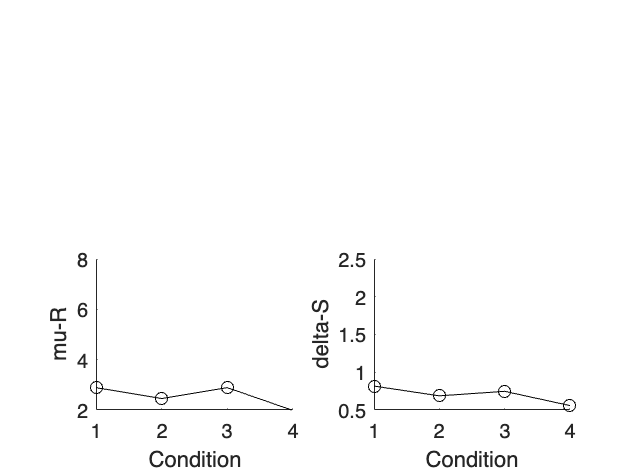



% 5. Evaluate the fits

% Plot the fits
for xx = 1:2
   
   subplot(2,2,2+xx); cla reset; hold on;
   plot(fits(:,xx), 'ko-');
end
subplot(2,2,3);
axis([1 4 2 8]);
xlabel('Condition')
ylabel('mu-R');

subplot(2,2,4);
axis([1 4 0.5 2.5]);
xlabel('Condition')
ylabel('delta-S');

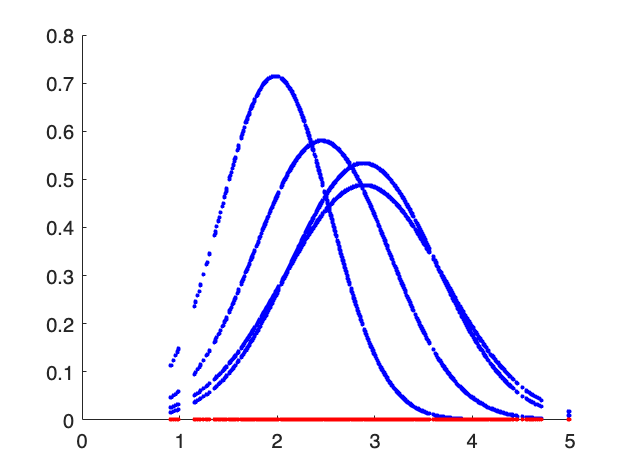


% % Display the best-fitting parameter values
% disp('Best-fitting parameter values:');
% disp(fits);
% 
% % Evaluate the negative log-likelihood of the best-fitting parameters
% bestNLLK = -nllk;
% disp(['Negative Log-Likelihood of the Best Fit: ', num2str(bestNLLK)]);
% 
% % Compute other statistics or perform model comparison as needed
% % For example, you can compare the model fit to the data by plotting the
% % model predictions against the actual data. Here's a simple example:
% 
% % Generate model predictions using the best-fitting parameters

reciprocalRTs_check=1./data{1};
bestFitPredictions = 1 ./ (fits(:, 2) * sqrt(2 * pi)) .* exp(-((reciprocalRTs_check - fits(:, 1)).^2) ./ (2 * fits(:, 2).^2));
% 
% 
% % Plot the data and model predictions for visual inspection
figure;
scatter(reciprocalRTs_check, bestFitPredictions, 'b.'); % Blue dots for model predictions
hold on;
scatter(reciprocalRTs_check, zeros(size(RTs)), 'r.'); % Red dots for the actual data (assuming zero mean)

% 
% % You can add more plotting and evaluation as needed based on your specific model and data.
% 
% % Lastly, you may want to compare the fit quality to previous models or
% % perform model selection using measures such as AIC or BIC.
% 